## Questão 1

Dados

VH=0.7;    
eta = 1.05;   
CLalpha=4.1;  %1/rad
St=7;         %m²
alpha=10;     %grau
CmCG = -0.33 - 0.044*alpha

Para equilibrar os momentos no avião, é necessário que o coeficiente de momento seja igual a zero, dessa forma a contribuição do profundor para o coeficiente de momento somado ao $C_{\textrm{mCG}}$ já calculado deve ser nulo.


$$C_{mCG} + C_{m\delta e}\delta_e=0$$


Como o problema pede a area necessária do profundor, nos fornecendo os batentes do mesmo, concluimos que deveria ser calculada a area minima necessária para estabilizar a aeronave com o profundor no batente.


$$\tau = \frac{C_{mCG}}{\eta V_H C_{L_{\alpha,t}}\delta_e}$$


deltaE = deg2rad([-20]);
tau = CmCG./(eta*VH*CLalpha*deltaE)
Se = @(tau) St.*(0.342.*tau.^4 - 0.0287.*tau.^3 + 0.6028.*tau.^2 + 0.239.*tau);
Se_res = Se(tau)

Seria necessária uma area de 4.0942 m² para equilibrar o avião em um pouso com o ângulo de ataque de 10° e o profundor no batente de -20°.

## Questão 2

X_ca_wb = 0.235;
St_S    = 0.25;
eta     = 0.95;
VH      = 0.42;
dedalpha= 0.35;
CLalpha_wb = 0.095;
CLalpha_t = 0.075;
CLalpha = CLalpha_wb + eta*St_S*CLalpha_t*(1-dedalpha)
xn = X_ca_wb + eta*VH*(1-dedalpha)*CLalpha_t/CLalpha

## Questão 3

Che_alphat = -0.0045;
Che_deltae = -0.0065;
Che_0 = -0.005;
SeSt = 0.35;

syms tau
eq1 = (0.342.*tau.^4 - 0.0287.*tau.^3 + 0.6028.*tau.^2 + 0.239.*tau) == SeSt
tau = solve(eq1, tau)
tau = double(tau(1))
dClt_ddeltae = tau*CLalpha_t;
Cl_deltae = eta * St_S * dClt_ddeltae;
f = 1 - dClt_ddeltae*Che_alphat/(CLalpha_t * Che_deltae)
F = 1 - Cl_deltae*Che_alphat/(CLalpha*Che_deltae) * (1 - dedalpha)

xn = X_ca_wb + f/F * eta * VH * (1 - dedalpha)*CLalpha_t/CLalpha

## Questão 4

Dados da questão

clear 
S = 16.21;  %m²
rho_0 = 1.225;
g = 9.81;
VE = [40.7 48.7 56.3 69.3 39.8 46.9 55 67.5 38.9 46 54.5 68];   %m/s
W = [1656 1650 1649 1646 1466 1463 1461 1458 1293 1290 1288 1286];  %kg
it = [-1.5 0 1 2 -4.5 -2 -0.3 1 -7.2 -3.5 -1.5 0];                       %graus
x_cg = [238.5 238.5 238.5 238.5 220.5 220.5 220.5 220.5 204.3 204.3 204.3 204.3]; %cm

Como o voo é reto e nivelado, $W = L = \frac{1}{2}\rho V^2 SC_L$, portanto


$$C_L = \frac{2W}{\rho V^2 S}$$


Cl = 2.*W./(rho_0.*VE.^2*S);
Cl1 = Cl(1:4);
it1 = it(1:4);
Cl2 = Cl(5:8);
it2 = it(5:8);
Cl3 = Cl(9:12);
it3 = it(9:12);


[fitresult1, gof1] = fit_top(Cl1, it1);
[fitresult2, gof2] = fit_top(Cl2, it2);
[fitresult3, gof3] = fit_top(Cl3, it3);
x = 0.02:0.001:0.11;
figure
hold on
plot(Cl1, it1, 'bo')
plot(x, fitresult1(x), 'b')
plot(Cl2, it2, 'go')
plot(x, fitresult2(x), 'g')
plot(Cl3, it3, 'mo')
plot(x, fitresult3(x), 'm')
hold on
xlabel('C_L')
ylabel('i_t')
legend('238.5 cm', '', '220.5 cm', '', '204.3 cm')
hold off
ditdCl = [fitresult1.p1 fitresult2.p1 fitresult3.p1];
xcgs = flip(unique(x_cg));
[fitresulttop, goftop] = fit_top(xcgs, ditdCl);
xn = fsolve(fitresulttop, 0)
figure
hold on
plot(xcgs, ditdCl, 'bo')
plot(200:270, fitresulttop(200:270), 'b')
yline(0)
plot(xn, 0, 'r*')
grid on
str = sprintf('x_n = %.2f cm', xn);
legend('', '', '', str)
xlabel('X_{CG}')
ylabel('$\frac{\partial \delta_{e_{eq}}}{\partial C_{L_{eq}}}$', 'FontSize', 18,'interpreter','latex')

## Questão 5

format shortG
clear all
close all
clc

aircraft = struct('S',116, ...
    'c',3.862, ...
    'b',32.757,...
    'm',55788, ...
    'Ixx',8.215e5, ...
    'Iyy',3.344e6,...
    'Izz',4.057e6, ...
    'Ixz',1.789e5,...
    'i_l_deg',2, ...
    'i_r_deg',2, ...
    'tau_l_deg', 1.5,...
    'tau_r_deg', -1.5,...
    'x_l',4.899, ...
    'y_l',-5.064,...
    'z_l',1.435,...
    'x_r',4.899, ...
    'y_r',5.064,...
    'z_r',1.435,...
    'Tmax',100e3, ...
    'n_rho',0.8, ...
    'g', 9.80665);

%Condição de Operação - Cruzeiro
trim_par = struct('V',230.15, ...
    'h',11582.4, ...
    'gamma_deg',0, ...
    'thetadot_deg_s',0, ...
    'psidot_deg_s',0);

% Xtest = [
%     250
%     2
%     5
%     5
%     5000
%     0
%     2
%     10
%     10
%     15
%     10
%     0
%     ];
% Utest = [0.5; 0.5; -5; 5; 5; 5];
% [Xdot, Y] = dynamics(0,Xtest,Utest, aircraft)

### a) Resultados obtidos para as variáveis de estado, de controle e de sáida na condição de equilíbrio.

options = optimset('Display','iter','TolX',1e-10,'TolFun',1e-10);
x_eq_0 = zeros(13,1);
x_eq_0(1) = trim_par.V;
x_eq = fsolve(@trim_function,x_eq_0,options,trim_par, aircraft);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         14         2.55982                          7.33               1
     1         28         0.47507              1          0.705               1
     2         42     0.000173362        1.62056        0.00821             2.5
     3         56     6.17015e-14      0.0158672       2.05e-07            4.05
     4         70     1.80289e-28    5.31626e-07       6.33e-14            4.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

[~,X_eq,U_eq, Y_eq] = trim_function(x_eq,trim_par,aircraft);
    
trim_output.X_eq = X_eq;
trim_output.U_eq = U_eq;
trim_output.Y_eq = Y_eq;

fprintf('----- Cruze FLIGHT CONDITION -----\n\n');

----- Cruze FLIGHT CONDITION -----



fprintf('   %-10s = %10.4f %-4s\n','gamma',trim_par.gamma_deg,'deg');

   gamma      =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','theta_dot',trim_par.thetadot_deg_s,'deg/s');

   theta_dot  =     0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','psi_dot',trim_par.psidot_deg_s,'deg/s');

   psi_dot    =     0.0000 deg/s


fprintf('\n');
fprintf('   %-10s = %10.2f %-4s\n','V',X_eq(1),'m/s');

   V          =     230.15 m/s 


fprintf('   %-10s = %10.4f %-4s\n','alpha',X_eq(2),'deg');

   alpha      =     1.7686 deg 


fprintf('   %-10s = %10.4f %-4s\n','q',X_eq(3),'deg/s');

   q          =     0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','theta',X_eq(4),'deg');

   theta      =     1.7686 deg 


fprintf('   %-10s = %10.1f %-4s\n','h',X_eq(5),'m');

   h          =    11582.4 m   


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','beta',X_eq(7),'deg');

   beta       =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','phi',X_eq(8),'deg');

   phi        =    -0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','p',X_eq(9),'deg/s');

   p          =    -0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','r',X_eq(10),'deg/s');

   r          =    -0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','psi',X_eq(11),'deg');

   psi        =    -0.0000 deg 


fprintf('\n');
fprintf('   %-10s = %10.2f %-4s\n','throttle_l',U_eq(1)*100,'%');

   throttle_l =      42.08 %   


fprintf('   %-10s = %10.2f %-4s\n','throttle_r',U_eq(2)*100,'%');

   throttle_r =      42.08 %   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_L',Y_eq(2),'N');

   Thrust_L   =   14808.02 N   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_R',Y_eq(3),'N');

   Thrust_R   =   14808.02 N   


fprintf('   %-10s = %10.4f %-4s\n','i_t',U_eq(3),'deg');

   i_t        =    -0.4495 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_e',U_eq(4),'deg');

   delta_e    =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_a',U_eq(5),'deg');

   delta_a    =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_r',U_eq(6),'deg');

   delta_r    =     0.0000 deg 


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','Mach',Y_eq(4),'');

   Mach       =     0.7800     


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','C_D',Y_eq(5),'');

   C_D        =     0.0290     


fprintf('   %-10s = %10.4f %-4s\n','C_L',Y_eq(6),'');

   C_L        =     0.5345     


fprintf('   %-10s = %10.4f %-4s\n','C_m',Y_eq(7),'');

   C_m        =    -0.0121     


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','C_Y',Y_eq(8),'');

   C_Y        =    -0.0000     


fprintf('   %-10s = %10.4f %-4s\n','C_l',Y_eq(9),'');

   C_l        =    -0.0000     


fprintf('   %-10s = %10.4f %-4s\n','C_n',Y_eq(10),'');

   C_n        =    -0.0000     


fprintf('\n');

#### Margem estática a manche fixo


$$K_n = -\frac{C_{m_{\alpha,CG}}}{C_{L_\alpha}}$$


Cm_alpha = -0.0402; %Tabela 3
CL_alpha = 0.133;   %Tabela 2
Kn = -(Cm_alpha/CL_alpha)

Kn =       0.30226

#### Autovalores da dinâmica linearizada

lin_output = struct('A',zeros(length(X_eq),length(X_eq)),...
    'B',zeros(length(X_eq),length(U_eq)),...
    'C',zeros(length(Y_eq),length(X_eq)),...
    'D',zeros(length(Y_eq),length(U_eq)));

step_val = 1e-5;

X_eq = trim_output.X_eq;
U_eq = trim_output.U_eq;
Y_eq = trim_output.Y_eq;

A = zeros(length(X_eq),length(X_eq));
C = zeros(length(Y_eq),length(X_eq));
for j=1:length(X_eq)
    dX = zeros(length(X_eq),1);
    dX(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq+dX,U_eq, aircraft);
    [Xdot_m,Y_m] = dynamics(0,X_eq-dX,U_eq, aircraft);
    A(:,j) = (Xdot_p - Xdot_m)/(2*dX(j));
    C(:,j) = (Y_p - Y_m)/(2*dX(j));
end

B = zeros(length(X_eq),length(U_eq));
D = zeros(length(Y_eq),length(U_eq));
for j=1:length(U_eq)
    dU = zeros(length(U_eq),1);
    dU(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq,U_eq+dU, aircraft);
    [Xdot_m,Y_m] = dynamics(0,X_eq,U_eq-dU, aircraft);
    B(:,j) = (Xdot_p - Xdot_m)/(2*dU(j));
    D(:,j) = (Y_p - Y_m)/(2*dU(j));
end

lin_output.A = A;
lin_output.B = B;
lin_output.C = C;
lin_output.D = D;

eigval = eig(lin_output.A([1:5 7:11],[1:5 7:11]))

eigval =             0 +          0i
     -0.58612 +     1.6377i
     -0.58612 -     1.6377i
   -0.0010993 +   0.066044i
   -0.0010993 -   0.066044i
   -0.0011109 +          0i
       -2.176 +          0i
     -0.11181 +      1.673i
     -0.11181 -      1.673i
    -0.008708 +          0i


damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -5.86e-01 + 1.64e+00i     3.37e-01       1.74e+00          1.71e+00    
 -5.86e-01 - 1.64e+00i     3.37e-01       1.74e+00          1.71e+00    
 -1.10e-03 + 6.60e-02i     1.66e-02       6.61e-02          9.10e+02    
 -1.10e-03 - 6.60e-02i     1.66e-02       6.61e-02          9.10e+02    
 -1.11e-03                 1.00e+00       1.11e-03          9.00e+02    
 -2.18e+00                 1.00e+00       2.18e+00          4.60e-01    
 -1.12e-01 + 1.67e+00i     6.67e-02       1.68e+00 

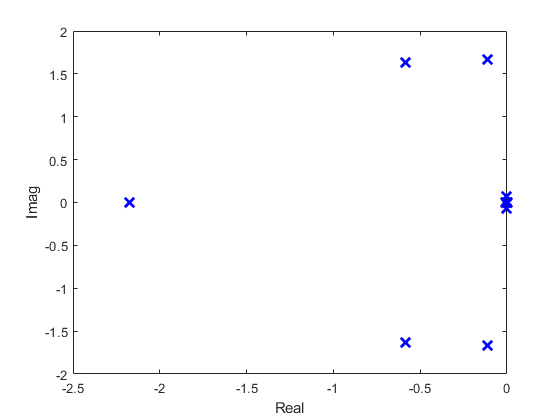

figure
plot(real(eig(A)),imag(eig(A)),'bx','MarkerSize',10,'LineWidth',2)
xlabel('Real')
ylabel('Imag')

Os três primeiros autovalores correspondem as variáveis de estado $x
$, $\psi$ e $y$ e dizemos que são "estados ignoráveis" para fins de análise de estabildade.

O par complexo (-1.1E-03 $\pm$ i6.6E-02) é o par complexo mais próximo da origem do plano complexo e corresponde a fugóide.

O par complexo (-5.86E-01 $\pm$ i1.64) é o par complexo mais distante da origem do plano complexo e corresponde ao modo de curto período.

O autovalor -1.1E-03 corresponde a pequena influência da altitude nas cargas aerodinâmicas e/ou propulsivas.

O par complexo (-1.12E-01 $\pm$ i1.67) corresponde ao Dutch roll.

O autovalor -2.18 corresponde ao modo de rolamento puro.

O autovalor -8.71E-03 corresponde ao modo espiral.

### b) Doublet

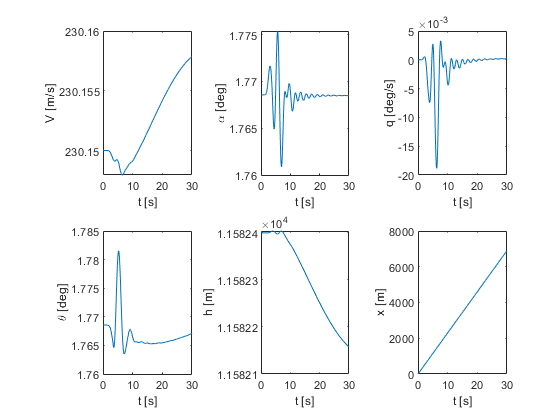

dt = 0.050;
tF = 30;

X0 = trim_output.X_eq;
U0 = trim_output.U_eq;

T = 0:dt:tF;

[X,Y] = ode4xy(@throttle_doublet,T,X0,U0, aircraft);

U = Y(:,11:16);
Y = Y(:,1:10);

figure
plot_long

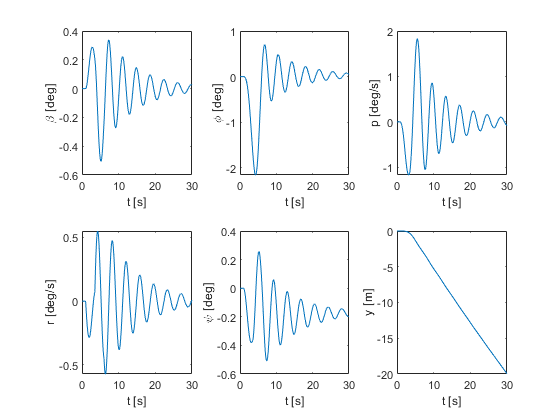

figure
plot_latdir

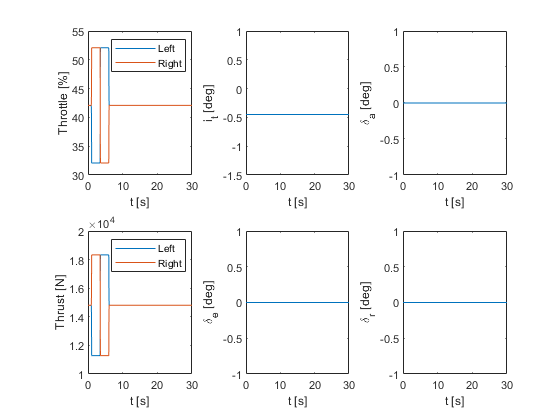

figure
plot_controls

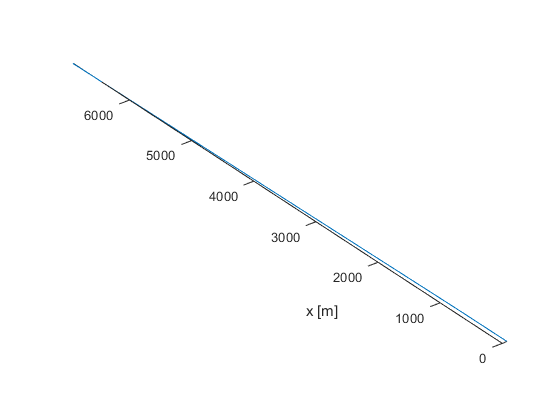

figure
plot_path

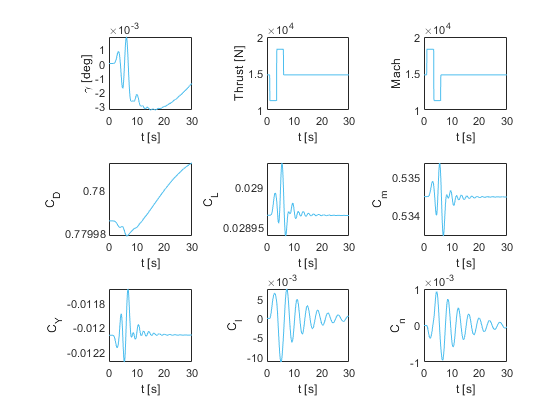

figure
plot_outputs

function [Xdot,Y] = throttle_doublet(t,X,U_eq, aircraft)
    U = U_eq;
    
    if t>=1 && t<=3.5
        U(1) = U(1) - 0.1;
        U(2) = U(2) + 0.1;
    elseif t>3.5 && t<=6
        U(1) = U(1) + 0.1;
        U(2) = U(2) - 0.1;
    end
    
    [Xdot,Y] = dynamics(t,X,U,aircraft);
    
    Y = [
        Y
        U
        ];
end

function [fitresult, gof] = fit_top(x, y)
[xData, yData] = prepareCurveData(x, y);

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );
end
